% MIMO UPLINK: ZF vs LMMSE DETAYLI ANALİZ
clc; clear; close all;

% --- SİSTEM PARAMETRELERİ --- uplink 
M_verici = 4;           
M_alici = 8;           
N_qam = 4;              
bit_per_sym = log2(N_qam);
bits_per_signal = M_verici * bit_per_sym; 
sym_per_trial=10000

sym_per_trial = 10000

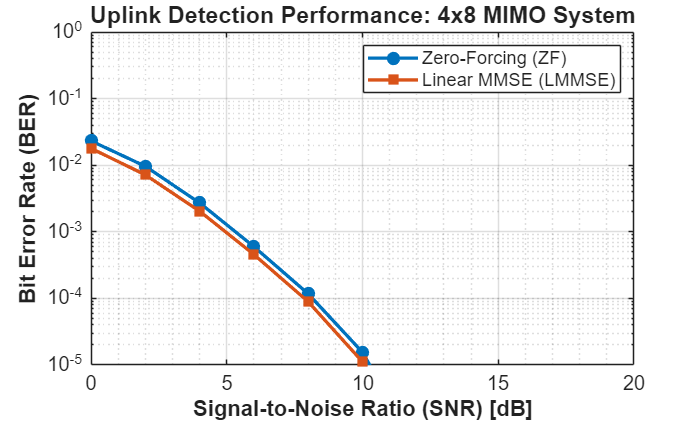

SNR_dB = 0:2:20;      % 1'er dB aralıkla daha sık veri noktası
num_trials = 1000;   % Hassasiyeti artırdık (Çizgilerin uzaması için)

BER_ZF = zeros(length(SNR_dB), 1);
BER_LMMSE = zeros(length(SNR_dB), 1);

% --- SİMÜLASYON DÖNGÜSÜ ---
for i = 1:length(SNR_dB)
    snr_current_dB = SNR_dB(i);
    SNR_linear = 10^(snr_current_dB / 10);
    P_noise = 1 / SNR_linear; 
    
    total_error_ZF = 0;
    total_error_LMMSE = 0;
    sent_bits = 0;

% --- SİMAULASYON DÖNGÜSÜ İÇİNDEKİ GÜNCELLEME (DIVERSITY) ---
for j = 1:num_trials
    % 1. Tek bir veri akışı oluştur (Diversity olduğu için her anten aynı veriyi basacak)
    total_bits = bit_per_sym * sym_per_trial*M_verici; 
    tx_bits = randi([0 1], total_bits, 1);
    
    % Sembolleri oluştur (1 x 10000)
    s = qammod(tx_bits, N_qam, 'gray', 'InputType', 'bit', 'UnitAveragePower', true).'; 
    X_last = reshape(s, [], M_verici);
    % --- DIVERSITY ADIMI ---
    % Aynı sembolü tüm M_verici antenlere kopyala (Boyut: 4 x 10000)
    
    
    H = (randn(M_alici, M_verici) + 1i * randn(M_alici, M_verici)) / sqrt(2);
    noise = (randn(M_alici, sym_per_trial) + 1i * randn(M_alici, sym_per_trial)) * sqrt(P_noise / 2);
    
    % Y = H * X + n (Boyutlar: [8x4] * [4x10000] + [8x10000] = [8x10000])
    Y_noisy = H * (X_last.') + noise;
    

    % --- ALICI (Combining) ---
    % Diversity senaryosunda ZF ve LMMSE "birleştirici" (combiner) gibi çalışır
    W_zf = pinv(H); 
    Y_rec_zf = W_zf * Y_noisy;
    % Gelen sembollerin ortalamasını alarak diversity kazancını yakala
     

    W_lmmse = (inv(H' * H + (P_noise) * eye(M_verici))) * H';
    Y_rec_lmmse = W_lmmse * Y_noisy;
    

    % Demodülasyon (Boyutlar uyumlu hale geldi)
    rx_bits_zf = qamdemod(Y_rec_zf.', N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);
    rx_bits_lmmse = qamdemod(Y_rec_lmmse.', N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);

    % Hata Hesabı
    total_error_ZF = total_error_ZF + biterr(tx_bits, rx_bits_zf(:));
    total_error_LMMSE = total_error_LMMSE + biterr(tx_bits, rx_bits_lmmse(:));
    
    sent_bits = sent_bits + total_bits;
end
    
    BER_ZF(i) = total_error_ZF / sent_bits;
    BER_LMMSE(i) = total_error_LMMSE / sent_bits;
end 

% --- PROFESYONEL GRAFİK DÜZENLEME ---
figure('Color', [1 1 1]); % Beyaz arka plan
semilogy(SNR_dB, BER_ZF, '-o', 'Color', [0 0.4470 0.7410], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', [0 0.4470 0.7410]); 
hold on;
semilogy(SNR_dB, BER_LMMSE, '-s', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

% Grafik Estetiği
grid on; set(gca, 'YMinorGrid', 'on', 'XMinorGrid', 'on', 'FontSize', 12);
xlabel('Signal-to-Noise Ratio (SNR) [dB]', 'FontWeight', 'bold');
ylabel('Bit Error Rate (BER)', 'FontWeight', 'bold');
title('Uplink Detection Performance: 4x8 MIMO System', 'FontSize', 14);

% Dinamik Legend
lgd = legend('Zero-Forcing (ZF)', 'Linear MMSE (LMMSE)');
set(lgd, 'Location', 'northeast', 'FontSize', 11);

% Eksen Limitleri (BER 0 olduğunda çizginin kesilmemesi için alt sınırı ayarladık)
xlim([min(SNR_dB) max(SNR_dB)]);
ylim([(1e-5 - 1e-16) 1]);